# TP Pourquoi passer en z ?

## Objectif : 

- Se rendre compte à travers un exemple concret de l'intérêt des outils de l'automatique échantillonnée. 

- Apprendre à manipuler Matlab/simulink.

- Commencer à utiliser la  transformée en z pour analyser les caractéristiques d'une boucle fermée et anticiper les résultats.

L'exemple consiste à asservir la vitesse d'un robot mobile (mesurée en mm/s) via un microcontrôleur (arduino mega2560). Le robot est actionné par deux moteurs CC alimentés par deux ponts en H pilotés par le µc. Le déplacement est mesuré par des encodeurs incrémentaux (quadrature) placés sur les arbres moteurs.

**Les questions et le travail à effectuer sont marqués en gras.**

Pour exécuter une section de code : `ctrl+enter`

Pour insérer du code : `ctrl+E`*.*

Pour insérer une équation dans le texte : `ctrl+shift+E`*.*

Le résultat s'affiche dans la zone de droite.

**Possibilité d'enregistrer ce livescript sous format pdf pour la remise de rapport.**

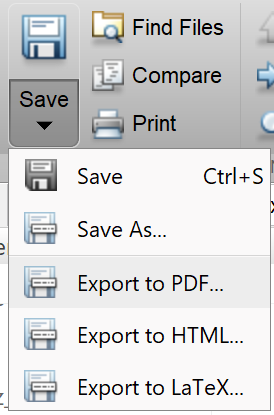

*Fonction matlab : *`help`

help help %ceci est un commentaire

## A. Modèle

On propose le modèle suivant pour le robot : 


$$\frac{v\left(s\right)}{u\left(s\right)}=F\left(s\right)=\frac{k}{\tau \;s+1}$$


avec $u\left(t\right)$ la tension du moteur (exprimée en V) et $v\left(t\right)$la vitesse longitudinale du robot (exprimée en mm/s).

**Ecrire un script permettant de déclarer la fonction de transfert de ce modèle et de tracer la réponse indicielle.**

% allez, c'est cadeau mais il faut quand même tout comprendre...

k= 300/7; % à ajuster si nécessaire [unités à préciser ici]
tau = 0.02; % à ajuster si nécessaire [s]

F = tf(k,[tau 1]) % pour plus d'infos : help tf

tfinal=0.3 % [s]

figure
hold on;
step(F,tfinal)
legend('Réponse à un échelon de 1');
title('Figure 1 : System Step Response');
grid on;
hold off;
%%


**Vérifier le modèle en boucle ouverte et ajuster les paramètres si nécessaire.**

open_system('OpenLoop.slx')

*Fichier utile : openloop.slx*

*Fonctions matlab: *`plot, hold`

% ecrire la solution ici 

**Donner les principales caractéristiques de la réponse et proposer un cahier des charges pour un asservissement de vitesse.**

*Fonction matlab: *`damp`

## B. Discrétisation

**Observer l'effet en simulation pour différentes périodes Te**

*Fonctions matlab:  *`tf, c2d, step, for`

Ensemble_de_Te_1=[0.002 0.005 0.01 0.02 0.1];
figure();
for Te=Ensemble_de_Te_1
   Te % compléter le script
   hold all
end

## C. Asservissement de vitesse

Par la suite, on désire réaliser un asservissement de vitesse qui répond à votre cahier des charges, en utilisant plusieurs méthodes de conception.

## D. Calcul d'un PI en continu

**Est-ce un bon choix ?**

*Objets utiles : cerveau(x)*

**Rappeler le schéma d'asservissement qui permet de déterminer les paramètres d'un correcteur PI: voir la préparation.**

**Rappeler votre cahier des charges (voir précédemment) en précisant la valeur numérique du temps de réponse.**

**A l'aide de votre préparation, écrire un script qui calcule Ti et Kp pour satisfaire les critères de votre cahier des charges.**

Kp=0;
Ti=0;


**A l'aide du fichier closeloop.slx, implémenter sur la maquette et tracer deux figures pour la réponse indicielle : **

- **consigne et vitesse sur une même figure**

- **commande sur une autre figure**

*Fichier utile : openloop.slx*

*Fonctions matlab: *`plot, hold`

% si besoin, ecrire un script ici

**Pourquoi la mesure de vitesse est-elle autant bruitée ?**

Piste : observer de près le signal de position et la méthode de calcul de la vitesse.

**Tripler la valeur du paramètre "Step Size". Noter cette nouvelle valeur. Tracer alors deux figures pour la réponse indicielle :**

- **consigne et vitesse sur une même figure**

- **commande sur une autre figure**

**Comment se comporte l'asservissement si la valeur de "Step Size" est triplée ? Comment évolue l'amplitude du bruit ?**

**Conclure sur l'efficacité du PI pour les deux valeurs du paramètre "Step Size" dont on rappellera les deux valeurs.**

## E. PRISE EN COMPTE DE LA NUMERISATION

**Sur papier, dessiner le schéma d'asservissement implanté sur la maquette : on y fera apparaître les fonctions ADC et DAC. **

**En déduire les fonctions de transfert en z utiles au calcul de la fonction de transfert en z de la boucle fermée.**

## Etude de l'effet d'échantillonnage

**Ecrire la fonction de transfert en z d'un PI discrétisé par la méthode d'Euler en gardant la période d'échantillonnage comme paramètre.** 

Rappel :  Euler dit que la dérivée $\frac{d}{\mathit{dt}}a\left(t\right)$ peut être approximée par  $\frac{\left(a_{k+1} -a_{k\;} \right)}{\mathit{Te}}$.

*ctrl+E pour insérer une équation dans le texte*.

*Objets utiles : cerveau, papier, crayon, *

*Fonctions Matlab :* `c2d, feedback`

**Pour plusieurs valeurs de la période d'échantillonnage, écrire un script qui calcule la fonction de transfert en discret de la boucle fermée et qui trace la réponse indicielles du système pour chacune des valeurs de la période d'échantillonnage.**

Ensemble_de_Te_2=[0.001:0.001:0.01 0.02:0.01:0.1];
for Te=Ensemble_de_Te_2
    Te % compléter le script
end

**Par une analyse des réponses indicielles, décrire comment influe le choix de la période d'échantillonnage sur la forme des réponses indicielles.**

**Afin d'affiner les remarques précédentes, compléter le code suivant pour réaliser un algorithme qui, en fonction de la période, trace la norme du plus grand pôle de la fonction de transfert en discret de la boucle fermée.**

*Fonctions Matlab :* `pzmap,norm, max`

indice=1;
tableau_pole=0;
for Te=Ensemble_de_Te_2
    Te % compléter le script
    tableau_pole(indice)=1;% remplacer 1 par la norme du plus grand pôle
    indice=indice+1;
end
figure();
plot(Ensemble_de_Te_2,tableau_pole, '*');
legend('Norme du plus grand des poles');
title('Figure 2 : Norme des poles');
xlabel('Valeur de Te (s)');
ylabel('Norme');
grid on;

**Quelle est la valeur de la période limite qui garantit la stabilité de l'asservissement ? Donner cette valeur à la milliseconde près.**

## Vérification des effets sur la maquette (tracer la réponse) pour un cas correct, un cas limite et un cas problématique (pour ce dernier cas, couper rapidement la tension).

**Placer dans votre compte rendu les schémas SIMULINK utilisés pour les différents cas.**

**Tracer alors deux figures pour la réponse indicielle :**

- **consigne et vitesse sur une même figure**

- **commande sur une autre figure**

**Décrire les courbes.**

**Comparer les résultats aux attentes du cahier des charges.**

**Conclure sur l'effet de l'échantillonnage sur un système asservi dont le correcteur a été calculé en continu.**

## F. Synthèse directe en discret

**Proposer un modèle échantillonné du schéma d'asservissement pour une synthèse directe en discret d'un correcteur numérique.**

**Choisir la valeur de période limite et, par une synthèse directe en discret, calculer les coefficients du correcteur qui satisfait votre cahier des charges (écrit plus haut).**

**Tester en simulation **

**Tester sur la maquette pour deux des trois cas précédents : cas limite et cas problématique.**

## Conclusion

**Quel est l'intérêt de la synthèse directe en z ?**

**Quels sont avantages à augmenter la période d'échantillonnage ?**

**Quels problèmes pourrait-on rencontrer si on augmente trop la période d'échantillonnage ?**